% check_all_hadamard_rows_by_sequency.m
% Runs the pipeline for every Hadamard row ordered by sequency.

N = 16;                    % Hadamard order (multiple of 4)
H = hadamard(N);
samplesPerChip = 20;
fs = 5000;
fc = 10;
snr_dB = 10;

% compute sequency (number of sign changes per row)
sequency = sum(abs(diff(H,1,2)), 2) / 2;   % integer count
[seqOrder, idx] = sort(sequency);          % idx: row indices sorted low->high sequency
H_sorted = H(idx, :);

numRows = size(H,1);
accuracies = zeros(numRows,1);
estSpp = zeros(numRows,1);
recoveredAll = cell(numRows,1);
sequency_sorted = sequency(idx);

for r = 1:numRows
    codeinput = H_sorted(r,:);
    % create analog signal
    analogSignal0 = repelem(codeinput, samplesPerChip);

    % simulate lossy I/O (WAV) - normalize then write/read
    audioVec = analogSignal0(:);
    if max(abs(audioVec))>0
        audioVec = audioVec / max(abs(audioVec));
    end
    tmpName = sprintf('temp_lossy_%d.wav', r);
    audiowrite(tmpName, audioVec, fs);
    [audioLossy, fs_read] = audioread(tmpName);
    if fs_read ~= fs
        audioLossy = resample(audioLossy, fs, fs_read);
    end
    audioLossy = audioLossy(:)'; delete(tmpName);
    analogSignal = audioLossy;

   
    % filter + AWGN
    filteredSignal = lowpass(analogSignal, fc, fs);
    noisySignal = awgn(filteredSignal, snr_dB, 'measured');

    

    % recovery 
    y = noisySignal(:)';
    y_smooth = movmedian(y, max(3, round(length(y)/1000)));
    digital_est = sign(y_smooth); digital_est(digital_est==0)=1;
    d = [true, diff(digital_est) ~= 0];
    idx_ch = find(d); idx_ch = [idx_ch, length(digital_est)+1];
    runLengths = diff(idx_ch); runValues = digital_est(idx_ch(1:end-1));
    if isempty(runLengths)
        est = 1;
    else
        uniqueLens = unique(runLengths);
        counts = histc(runLengths, uniqueLens);
        [~, order] = sort(counts, 'descend');
        K = min(3, numel(order));
        estCandidates = uniqueLens(order(1:K));
        est = max(1, round(median(estCandidates)));
        % merge tiny runs
        minRun = max(1, round(0.25 * est));
        if any(runLengths < minRun)
            mergedVals = runValues; mergedLens = runLengths; i = 1;
            while i <= length(mergedLens)
                if mergedLens(i) < minRun && length(mergedLens) > 1
                    if i == 1
                        mergedLens(2) = mergedLens(2) + mergedLens(1);
                        mergedVals(1) = []; mergedLens(1) = [];
                    else
                        mergedLens(i-1) = mergedLens(i-1) + mergedLens(i);
                        mergedVals(i) = []; mergedLens(i) = []; i = i-1;
                    end
                end
                i = i + 1;
            end
            runLengths = mergedLens;
            uniqueLens = unique(runLengths);
            counts = histc(runLengths, uniqueLens);
            [~, order] = sort(counts, 'descend'); K = min(3, numel(order));
            est = max(1, round(median(uniqueLens(order(1:K)))));
        end
    end

    % reconstruct chips and compare
    L = floor(length(y)/est)*est;
    X = reshape(y(1:L), est, []);
    chipStat = mean(X,1);
    recoveredChips = sign(chipStat); recoveredChips(recoveredChips==0)=1;
    numChips = min(length(recoveredChips), length(codeinput));
    rec = recoveredChips(1:numChips); orig = codeinput(1:numChips);
    accuracies(r) = sum(rec==orig)/numChips*100;
    estSpp(r) = est;
    recoveredAll{r} = rec;
end

% map sorted accuracies back to original row order
acc_by_orig = zeros(numRows,1);
acc_by_orig(idx) = accuracies;



% Create table: OriginalRow, Sequency, Accuracy
origRow = (1:numRows)';                     % original Hadamard row indices
sequency_by_orig = sequency;                % sequency already indexed by original rows
accuracy_by_orig = acc_by_orig;             % accuracy mapped back to original rows

T = table(origRow, sequency_by_orig, accuracy_by_orig, ...
    'VariableNames', {'OriginalRow','Sequency','Accuracy'});

% display table sorted by OriginalRow (default)
disp(sortrows(T, 'Accuracy', 'descend'));

    OriginalRow    Sequency    Accuracy
    ___________    ________    ________

         1             0           100 
         2            15           100 
         6            12           100 
        10            14           100 
        12             9         81.25 
         8            11            75 
        14            13         68.75 
        16            10        64.286 
        15             5         56.25 
         3             7            50 
         4             8            50 
         7             4            50 
         9             1            50 
        11             6            50 
         5             3         43.75 
        13             2        33.333 



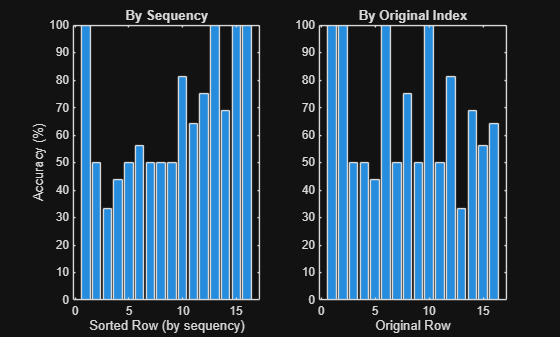




figure;
subplot(1,2,1);
bar(1:numRows, accuracies); xlabel('Sorted Row (by sequency)'); ylabel('Accuracy (%)'); title('By Sequency'); ylim([0 100]);
subplot(1,2,2);
bar(1:numRows, acc_by_orig); xlabel('Original Row'); title('By Original Index'); ylim([0 100]);